clc, clear
f = "00000077.BIN";
ard = ardupilotreader(f);

summaryTbl = readMessages(ard);  
unique(summaryTbl.MsgName) 

ans = 85×1 string array
    "ACC"
    "AHR2"
    "ANG"
    "ARM"
    "ATT"
    "AUXF"
    "BARO"
    "BAT"
    "CAND"
    "CANS"
    "CMD"
    "CTRL"
    "CTUN"
    "D32"
    "DCM"
    "DSF"
    "DU32"
    "EAHR"
    "ERR"
    "EV"
    "FILE"
    "FMT"
    "FMTU"
    "FNCE"
    "GPA"
    "GPS"
    "GYR"
    "HEAT"
    "IMU"
    "IOMC"



% Vytáhne obsah buňky na řádku 42 ve sloupci MsgData
imu1_data = summaryTbl.MsgData{42}; 
imu2_data = summaryTbl.MsgData{43};
imu3_data = summaryTbl.MsgData{44};
baro1_data = summaryTbl.MsgData{15};
baro2_data = summaryTbl.MsgData{16};
gps_data = summaryTbl.MsgData{7};
mag1_data = summaryTbl.MsgData{23};
mag2_data = summaryTbl.MsgData{24};

krok1 = imu1_data.timestamp(end) - imu1_data.timestamp(end-1);
krok2 = imu2_data.timestamp(end) - imu2_data.timestamp(end-1);
krok3 = imu3_data.timestamp(end) - imu3_data.timestamp(end-1);
krok4 = baro1_data.timestamp(end) - baro1_data.timestamp(end-1);
krok5 = baro2_data.timestamp(end) - baro2_data.timestamp(end-1);
krok6 = gps_data.timestamp(end) - gps_data.timestamp(end-1);
krok7 = mag1_data.timestamp(end) - mag1_data.timestamp(end-1);
krok8 = mag2_data.timestamp(end) - mag2_data.timestamp(end-1);


dt_imu1 = seconds(krok1)

dt_imu1 = 0.0024

dt_imu2 = seconds(krok2);
dt_imu3 = seconds(krok3);
dt_baro1 = seconds(krok4);
dt_baro2 = seconds(krok5);
dt_gps = seconds(krok6);
dt_mag1 = seconds(krok7);
dt_mag2 = seconds(krok8);

vsechny_kroky = [dt_imu1, dt_imu2, dt_imu3, dt_baro1, dt_baro2, dt_gps, dt_mag1, dt_mag2];
% Najdeme nejmenší nenulový krok
min_dt = min(vsechny_kroky(vsechny_kroky > 0));
fprintf('Nejrychlejší senzor má krok: %.5f s (Frekvence: %.1f Hz)\n', ...
        min_dt, 1/min_dt);

Nejrychlejší senzor má krok: 0.00245 s (Frekvence: 408.3 Hz)


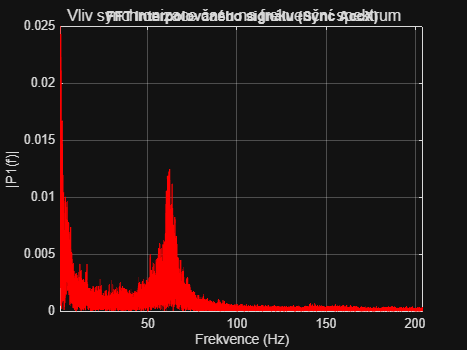

dt = min_dt;

% Musíme převést časy všech senzorů na sekundy pro interpolaci
t1 = seconds(imu1_data.timestamp); t2 = seconds(imu2_data.timestamp); t3 = seconds(imu3_data.timestamp);
tb1 = seconds(baro1_data.timestamp); tb2 = seconds(baro2_data.timestamp);
tg = seconds(gps_data.timestamp);
tm1 = seconds(mag1_data.timestamp); tm2 = seconds(mag2_data.timestamp);

% Najdeme společný začátek (nejpozdější start) a konec (nejdřívější stop)
t_start = max([t1(1), t2(1), t3(1), tb1(1), tb2(1), tg(1), tm1(1), tm2(1)]);
t_end   = min([t1(end), t2(end), t3(end), tb1(end), tb2(end), tg(end), tm1(end), tm2(end)]);

pozadovana_delka = 412; % POSUN
t_end_cut = t_start + pozadovana_delka;
t_common = (t_end_cut : dt : t_end)';

data = struct();
data.Time = t_common;
% --- IMU 1 ---
data.IMU1.Acc = [interp1(t1, imu1_data.AccX, t_common, 'linear'), ...
                 interp1(t1, imu1_data.AccY, t_common, 'linear'), ...
                 interp1(t1, imu1_data.AccZ, t_common, 'linear')];

data.IMU1.Gyr = [interp1(t1, imu1_data.GyrX, t_common, 'linear'), ...
                 interp1(t1, imu1_data.GyrY, t_common, 'linear'), ...
                 interp1(t1, imu1_data.GyrZ, t_common, 'linear')];

% --- IMU 2 ---
data.IMU2.Acc = [interp1(t2, imu2_data.AccX, t_common, 'linear'), ...
                 interp1(t2, imu2_data.AccY, t_common, 'linear'), ...
                 interp1(t2, imu2_data.AccZ, t_common, 'linear')];

data.IMU2.Gyr = [interp1(t2, imu2_data.GyrX, t_common, 'linear'), ...
                 interp1(t2, imu2_data.GyrY, t_common, 'linear'), ...
                 interp1(t2, imu2_data.GyrZ, t_common, 'linear')];

% --- IMU 3 ---
data.IMU3.Acc = [interp1(t3, imu3_data.AccX, t_common, 'linear'), ...
                 interp1(t3, imu3_data.AccY, t_common, 'linear'), ...
                 interp1(t3, imu3_data.AccZ, t_common, 'linear')];

data.IMU3.Gyr = [interp1(t3, imu3_data.GyrX, t_common, 'linear'), ...
                 interp1(t3, imu3_data.GyrY, t_common, 'linear'), ...
                 interp1(t3, imu3_data.GyrZ, t_common, 'linear')];

% --- BAROMETRY ---
data.Baro1.Alt = interp1(tb1, baro1_data.Alt, t_common, 'linear');
data.Baro2.Alt = interp1(tb2, baro2_data.Alt, t_common, 'linear');

% --- MAGNETOMETRY ---
data.Mag1.Field = [interp1(tm1, mag1_data.MagX, t_common, 'linear'), ...
                   interp1(tm1, mag1_data.MagY, t_common, 'linear'), ...
                   interp1(tm1, mag1_data.MagZ, t_common, 'linear')];

data.Mag2.Field = [interp1(tm2, mag2_data.MagX, t_common, 'linear'), ...
                   interp1(tm2, mag2_data.MagY, t_common, 'linear'), ...
                   interp1(tm2, mag2_data.MagZ, t_common, 'linear')];

% --- GPS ---
data.GPS.Pos = [interp1(tg, gps_data.Lat, t_common, 'linear'), ...
                interp1(tg, gps_data.Lng, t_common, 'linear'), ...
                interp1(tg, gps_data.Alt, t_common, 'linear')]; % [Lat, Lon, Alt]

data.GPS.Spd = interp1(tg, gps_data.Spd, t_common, 'linear');
data.GPS.GCRs = interp1(tg, gps_data.GCrs, t_common, 'linear');
data.GPS.VZ = interp1(tg, gps_data.VZ, t_common, 'linear');



interp_sig = data.IMU1.Acc(:, 1); 
Fs_new = 1/dt;  
L_new = length(interp_sig);  
% --- VÝPOČET FFT PRO INTERPOLOVANÝ SIGNÁL ---
Y_new = fft(interp_sig - mean(interp_sig)); 
P2_new = abs(Y_new/L_new); 
P1_new = P2_new(1:floor(L_new/2)+1);   
P1_new(2:end-1) = 2*P1_new(2:end-1);
f_new = Fs_new*(0:(L_new/2))/L_new;

% --- VYKRESLENÍ POROVNÁNÍ ---
figure('Name', 'Porovnání FFT: Raw vs Interpolated');

% Graf 2: Interpolovaná data
plot(f_new, P1_new, 'r', 'LineWidth', 1);
title('FFT Interpolovaného signálu (Sync AccX)');
xlabel('Frekvence (Hz)'); ylabel('|P1(f)|');
grid on; xlim([1, Fs_new/2]); %posunuto o 1 sekundu pro lepsi znazorneni šumu

sgtitle('Vliv synchronizace času na frekvenční spektrum');

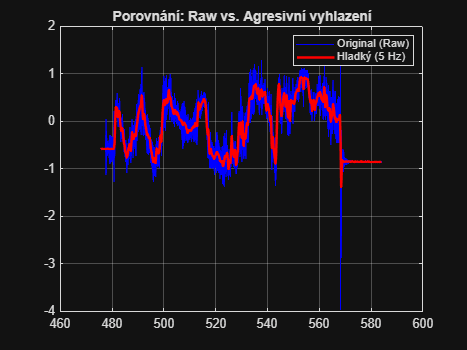



%POKUD VAM KALMAN BUDE BLBNOUT KVULI IMU ZE MATE MALE ZASAHY TAK ZVYSTE
%FCSMOOTH A DEJTE HO TREBA NA 20HZ
%!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
fc_smooth = 1.5;       % Cut-off (velmi nízká = velmi hladké)
Fs = 1/dt; 
% FILTR
[b, a] = butter(2, fc_smooth / (Fs/2), 'low');

%IMU1
acc1X_smooth = filtfilt(b, a, data.IMU1.Acc(:,1));
acc1Y_smooth = filtfilt(b, a, data.IMU1.Acc(:,2));
acc1Z_smooth = filtfilt(b, a, data.IMU1.Acc(:,3));
%IMU2
acc2X_smooth = filtfilt(b, a, data.IMU2.Acc(:,1));
acc2Y_smooth = filtfilt(b, a, data.IMU2.Acc(:,2));
acc2Z_smooth = filtfilt(b, a, data.IMU2.Acc(:,3));
%IMU3
acc3X_smooth = filtfilt(b, a, data.IMU3.Acc(:,1));
acc3Y_smooth = filtfilt(b, a, data.IMU3.Acc(:,2));
acc3Z_smooth = filtfilt(b, a, data.IMU3.Acc(:,3));

% Vykreslení TOHO UPRAVENEHO SIGNALU A STAREHO ABY JSTE SI TO POROVNALI
figure;
plot(t_common, data.IMU2.Acc(:,1), 'b', 'DisplayName', 'Original (Raw)');
hold on;
plot(t_common, acc2X_smooth, 'r', 'LineWidth', 2, 'DisplayName', 'Hladký (5 Hz)');
title('Porovnání: Raw vs. Agresivní vyhlazení');
legend; grid on;

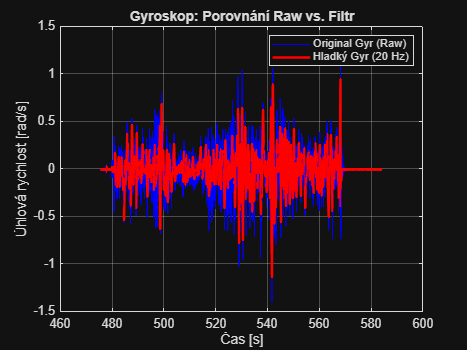

%Ulozeni
data.IMU1.Acc = [acc1X_smooth, ...
                 acc1Y_smooth, ...
                 acc1Z_smooth];
data.IMU2.Acc = [acc2X_smooth, ...
                 acc2Y_smooth, ...
                 acc2Z_smooth];
data.IMU3.Acc = [acc3X_smooth, ...
                 acc3Y_smooth, ...
                 acc3Z_smooth];


%% FILTRACE GYROSKOPŮ
fc_smooth = 20; % Cut-off (velmi nízká = velmi hladké)
Fs = 1/dt;
[b, a] = butter(2, fc_smooth / (Fs/2), 'low');

% IMU 1 - Gyroskop
gyr1X_smooth = filtfilt(b, a, data.IMU1.Gyr(:,1));
gyr1Y_smooth = filtfilt(b, a, data.IMU1.Gyr(:,2));
gyr1Z_smooth = filtfilt(b, a, data.IMU1.Gyr(:,3));

% IMU 2 - Gyroskop
gyr2X_smooth = filtfilt(b, a, data.IMU2.Gyr(:,1));
gyr2Y_smooth = filtfilt(b, a, data.IMU2.Gyr(:,2));
gyr2Z_smooth = filtfilt(b, a, data.IMU2.Gyr(:,3));

% IMU 3 - Gyroskop
gyr3X_smooth = filtfilt(b, a, data.IMU3.Gyr(:,1));
gyr3Y_smooth = filtfilt(b, a, data.IMU3.Gyr(:,2));
gyr3Z_smooth = filtfilt(b, a, data.IMU3.Gyr(:,3));

%VYKRESLENÍ KONTROLY (GYRO)
figure;
% Vykreslíme např. IMU2 Osu X (sloupec 1)
plot(t_common, data.IMU2.Gyr(:,1), 'b', 'DisplayName', 'Original Gyr (Raw)');
hold on;
plot(t_common, gyr2X_smooth, 'r', 'LineWidth', 2, 'DisplayName', ['Hladký Gyr (' num2str(fc_smooth) ' Hz)']);
title('Gyroskop: Porovnání Raw vs. Filtr');
xlabel('Čas [s]');
ylabel('Úhlová rychlost [rad/s]');
legend; grid on;

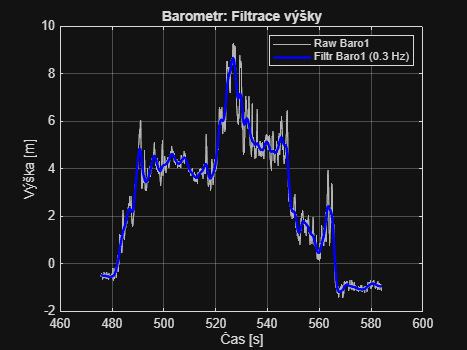


%ULOŽENÍ ZPĚT DO STRUKTURY
data.IMU1.Gyr = [gyr1X_smooth, ...
                 gyr1Y_smooth, ...
                 gyr1Z_smooth];

data.IMU2.Gyr = [gyr2X_smooth, ...
                 gyr2Y_smooth, ...
                 gyr2Z_smooth];

data.IMU3.Gyr = [gyr3X_smooth, ...
                 gyr3Y_smooth, ...
                 gyr3Z_smooth];


%% FILTRACE BAROMETRŮ (VÝŠKA)
fc_baro = 0.3; %hodne vyhlazene !!!!!!!!
Fs = 1/dt;
[b_baro, a_baro] = butter(2, fc_baro / (Fs/2), 'low');
% Barometr 1
baro1_alt_smooth = filtfilt(b_baro, a_baro, data.Baro1.Alt);
% Barometr 2
baro2_alt_smooth = filtfilt(b_baro, a_baro, data.Baro2.Alt);
%VYKRESLENÍ KONTROLY (BARO) 
figure;
plot(t_common, data.Baro2.Alt, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Raw Baro1');
hold on;
plot(t_common, baro2_alt_smooth, 'b', 'LineWidth', 2, 'DisplayName', ['Filtr Baro1 (' num2str(fc_baro) ' Hz)']);
title('Barometr: Filtrace výšky');
xlabel('Čas [s]');
ylabel('Výška [m]');
legend; grid on;

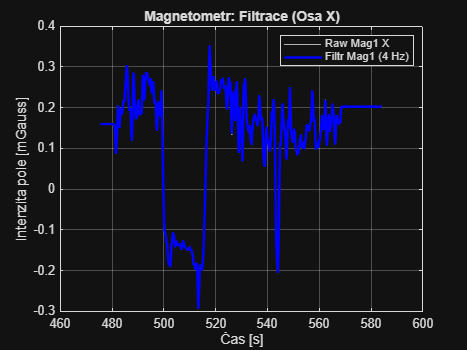

%ULOŽENÍ ZPĚT DO STRUKTURY
data.Baro1.Alt = baro1_alt_smooth;
data.Baro2.Alt = baro2_alt_smooth;


%% FILTRACE MAGNETOMETRŮ 
fc_mag = 4; %minimalne vyfiltrovane
Fs = 1/dt;
[b_mag1, a_mag1] = butter(2, fc_mag / (Fs/2), 'low');
[b_mag2, a_mag2] = butter(2, 1 / (Fs/2), 'low');

% Filtrujeme celou matici [X, Y, Z] jen tak ..proc ne 
mag1_field_smooth = filtfilt(b_mag1, a_mag1, data.Mag1.Field);
mag2_field_smooth = filtfilt(b_mag2, a_mag2, data.Mag2.Field);

figure;
plot(t_common, data.Mag1.Field(:,1), 'Color', [0.7 0.7 0.7], 'DisplayName', 'Raw Mag1 X');
hold on;
plot(t_common, mag1_field_smooth(:,1), 'b', 'LineWidth', 2, 'DisplayName', ['Filtr Mag1 (' num2str(fc_mag) ' Hz)']);
title('Magnetometr: Filtrace (Osa X)');
xlabel('Čas [s]');
ylabel('Intenzita pole [mGauss]');
legend; grid on;

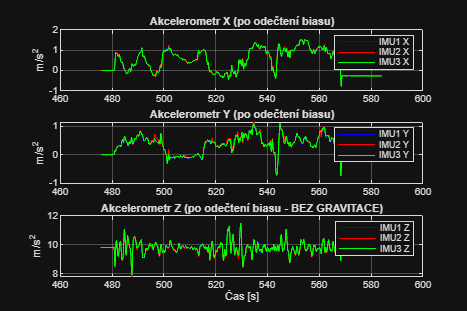

%ULOŽENÍ ZPĚT DO STRUKTURY
data.Mag1.Field = mag1_field_smooth;
data.Mag2.Field = mag2_field_smooth;


%% KALIBRACE BIASU (OFFSETU)
% Určení času pro kalibraci (první 1 sekunda)
delka_kalibrace = 1.0; % ta 1 sekunda
idx_ = delka_kalibrace/dt;
idx_bias = 1:idx_;
GRAVITACE = 9.80665;

%IMU 1
bias_acc1 = mean(data.IMU1.Acc(idx_bias, :)); 
bias_gyr1 = mean(data.IMU1.Gyr(idx_bias, :)); 
rozdil_gyr1 = bias_acc1(3) - GRAVITACE;

data.IMU1.Acc(:,1:2) = data.IMU1.Acc(:,1:2) - bias_acc1(1:2);
data.IMU1.Acc(:,3) = data.IMU1.Acc(:,3) - rozdil_gyr1;
data.IMU1.Gyr = data.IMU1.Gyr - bias_gyr1;

%IMU 2
bias_acc2 = mean(data.IMU2.Acc(idx_bias, :));
bias_gyr2 = mean(data.IMU2.Gyr(idx_bias, :));
rozdil_gyr2 = bias_acc2(3) - GRAVITACE;
data.IMU2.Acc(:,1:2) = data.IMU2.Acc(:,1:2) - bias_acc2(1:2);
data.IMU2.Acc(:,3) = data.IMU2.Acc(:,3) - rozdil_gyr2;
data.IMU2.Gyr = data.IMU2.Gyr - bias_gyr2;


%IMU 3
bias_acc3 = mean(data.IMU3.Acc(idx_bias, :));
bias_gyr3 = mean(data.IMU3.Gyr(idx_bias, :));
rozdil_gyr3 = bias_acc3(3) - GRAVITACE;
data.IMU3.Acc(:,1:2) = data.IMU3.Acc(:,1:2) - bias_acc3(1:2);
data.IMU3.Acc(:,3) = data.IMU3.Acc(:,3) - rozdil_gyr3;
data.IMU3.Gyr = data.IMU3.Gyr - bias_gyr3;


%BAROMETRY (Srovnání výšky na 0)
bias_baro1 = mean(data.Baro1.Alt(idx_bias));
bias_baro2 = mean(data.Baro2.Alt(idx_bias));

data.Baro1.Alt = data.Baro1.Alt - bias_baro1;
data.Baro2.Alt = data.Baro2.Alt - bias_baro2;


%MAGNETOMETRY ten druhej je uplne kaput frfr sumi extremne a mel
% spatnou hodnotu tak jsem zvolil vychozi toho prvniho :)
bias_mag1 = mean(data.Mag1.Field(idx_bias, :));
bias_mag2 = mean(data.Mag2.Field(idx_bias, :));
rozdil_magX = bias_mag1(1) - bias_mag2(1);
rozdil_magY = bias_mag1(2) - bias_mag2(2);
rozdil_magZ = bias_mag1(3) - bias_mag2(3);
data.Mag2.Field(:,1) = data.Mag2.Field(:,1) + rozdil_magX;
data.Mag2.Field(:,2) = data.Mag2.Field(:,2) + rozdil_magY;
data.Mag2.Field(:,3) = data.Mag2.Field(:,3) + rozdil_magZ;


%% VIZUALIZACE VŠECH VYNULOVANÝCH DAT
% 1. AKCELEROMETRY (Porovnání všech 3 IMU)
figure('Name', 'Vynulované Akcelerometry (IMU 1, 2, 3)', 'Position', [100, 100, 1200, 800]);

% Osa X
ax1 = subplot(3,1,1);
plot(data.Time, data.IMU1.Acc(:,1), 'b', 'DisplayName', 'IMU1 X'); hold on;
plot(data.Time, data.IMU2.Acc(:,1), 'r', 'DisplayName', 'IMU2 X');
plot(data.Time, data.IMU3.Acc(:,1), 'g', 'DisplayName', 'IMU3 X');
title('Akcelerometr X (po odečtení biasu)'); ylabel('m/s^2'); legend; grid on;

% Osa Y
ax2 = subplot(3,1,2);
plot(data.Time, data.IMU1.Acc(:,2), 'b', 'DisplayName', 'IMU1 Y'); hold on;
plot(data.Time, data.IMU2.Acc(:,2), 'r', 'DisplayName', 'IMU2 Y');
plot(data.Time, data.IMU3.Acc(:,2), 'g', 'DisplayName', 'IMU3 Y');
title('Akcelerometr Y (po odečtení biasu)'); ylabel('m/s^2'); legend; grid on;

% Osa Z (Tady uvidíte, že to je kolem 0, nikoliv -9.81)
ax3 = subplot(3,1,3);
plot(data.Time, data.IMU1.Acc(:,3), 'b', 'DisplayName', 'IMU1 Z'); hold on;
plot(data.Time, data.IMU2.Acc(:,3), 'r', 'DisplayName', 'IMU2 Z');
plot(data.Time, data.IMU3.Acc(:,3), 'g', 'DisplayName', 'IMU3 Z');
title('Akcelerometr Z (po odečtení biasu - BEZ GRAVITACE)'); ylabel('m/s^2'); legend; grid on;
xlabel('Čas [s]');

linkaxes([ax1, ax2, ax3], 'x'); % Zoomování funguje na všech osách najednou

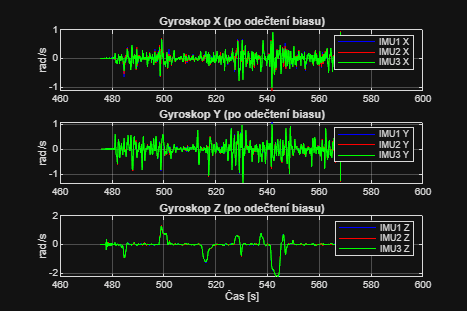



%2. GYROSKOPY (Porovnání všech 3 IMU)
figure('Name', 'Vynulované Gyroskopy (IMU 1, 2, 3)', 'Position', [150, 150, 1200, 800]);

% Osa X
gx1 = subplot(3,1,1);
plot(data.Time, data.IMU1.Gyr(:,1), 'b', 'DisplayName', 'IMU1 X'); hold on;
plot(data.Time, data.IMU2.Gyr(:,1), 'r', 'DisplayName', 'IMU2 X');
plot(data.Time, data.IMU3.Gyr(:,1), 'g', 'DisplayName', 'IMU3 X');
title('Gyroskop X (po odečtení biasu)'); ylabel('rad/s'); legend; grid on;

% Osa Y
gx2 = subplot(3,1,2);
plot(data.Time, data.IMU1.Gyr(:,2), 'b', 'DisplayName', 'IMU1 Y'); hold on;
plot(data.Time, data.IMU2.Gyr(:,2), 'r', 'DisplayName', 'IMU2 Y');
plot(data.Time, data.IMU3.Gyr(:,2), 'g', 'DisplayName', 'IMU3 Y');
title('Gyroskop Y (po odečtení biasu)'); ylabel('rad/s'); legend; grid on;

% Osa Z
gx3 = subplot(3,1,3);
plot(data.Time, data.IMU1.Gyr(:,3), 'b', 'DisplayName', 'IMU1 Z'); hold on;
plot(data.Time, data.IMU2.Gyr(:,3), 'r', 'DisplayName', 'IMU2 Z');
plot(data.Time, data.IMU3.Gyr(:,3), 'g', 'DisplayName', 'IMU3 Z');
title('Gyroskop Z (po odečtení biasu)'); ylabel('rad/s'); legend; grid on;
xlabel('Čas [s]');

linkaxes([gx1, gx2, gx3], 'x');

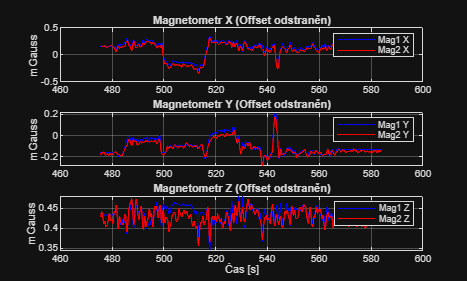



%3. MAGNETOMETRY (Porovnání Mag 1 a 2)
figure('Name', 'Vynulované Magnetometry', 'Position', [200, 200, 1000, 600]);

mx1 = subplot(3,1,1);
plot(data.Time, data.Mag1.Field(:,1), 'b', 'DisplayName', 'Mag1 X'); hold on;
plot(data.Time, data.Mag2.Field(:,1), 'r', 'DisplayName', 'Mag2 X');
title('Magnetometr X (Offset odstraněn)'); ylabel('mGauss'); legend; grid on;

mx2 = subplot(3,1,2);
plot(data.Time, data.Mag1.Field(:,2), 'b', 'DisplayName', 'Mag1 Y'); hold on;
plot(data.Time, data.Mag2.Field(:,2), 'r', 'DisplayName', 'Mag2 Y');
title('Magnetometr Y (Offset odstraněn)'); ylabel('mGauss'); legend; grid on;

mx3 = subplot(3,1,3);
plot(data.Time, data.Mag1.Field(:,3), 'b', 'DisplayName', 'Mag1 Z'); hold on;
plot(data.Time, data.Mag2.Field(:,3), 'r', 'DisplayName', 'Mag2 Z');
title('Magnetometr Z (Offset odstraněn)'); ylabel('mGauss'); legend; grid on;
xlabel('Čas [s]');

linkaxes([mx1, mx2, mx3], 'x');

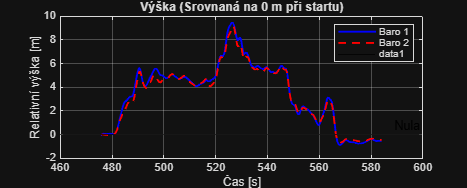



%4. BAROMETRY (Výška)
figure('Name', 'Vynulované Barometry', 'Position', [250, 250, 1000, 400]);

plot(data.Time, data.Baro1.Alt, 'b', 'LineWidth', 1.5, 'DisplayName', 'Baro 1'); hold on;
plot(data.Time, data.Baro2.Alt, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Baro 2');
yline(0, 'k-', 'Nula'); % Pomocná čára na nule
title('Výška (Srovnaná na 0 m při startu)');
ylabel('Relativní výška [m]');
xlabel('Čas [s]');
legend; grid on;

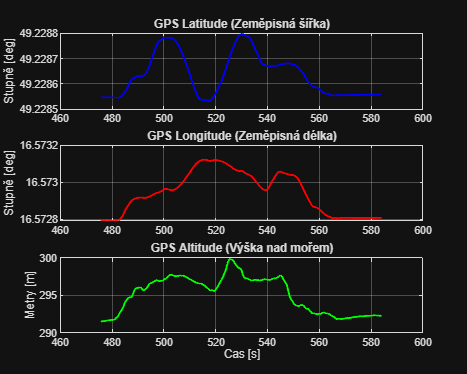


%% VIZUALIZACE GPS DAT
%1. POZICE (Latitude, Longitude, Altitude)
figure('Name', 'GPS: Pozice v čase', 'Position', [100, 100, 1000, 800]);
% Latitude (Zeměpisná šířka)
ax1 = subplot(3,1,1);
plot(data.Time, data.GPS.Pos(:,1), 'b', 'LineWidth', 1.5);
title('GPS Latitude (Zeměpisná šířka)');
ylabel('Stupně [deg]'); grid on;

% Longitude (Zeměpisná délka)
ax2 = subplot(3,1,2);
plot(data.Time, data.GPS.Pos(:,2), 'r', 'LineWidth', 1.5);
title('GPS Longitude (Zeměpisná délka)');
ylabel('Stupně [deg]'); grid on;

% Altitude (Výška)
ax3 = subplot(3,1,3);
plot(data.Time, data.GPS.Pos(:,3), 'g', 'LineWidth', 1.5);
title('GPS Altitude (Výška nad mořem)');
ylabel('Metry [m]'); xlabel('Čas [s]'); grid on;

linkaxes([ax1, ax2, ax3], 'x'); % Propojení zoomování

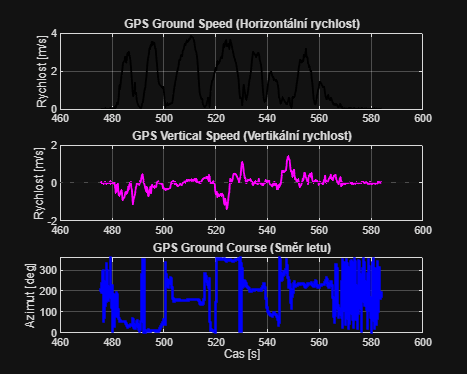



% 2. RYCHLOST A SMĚR (Speed, VZ, Course) ---
figure('Name', 'GPS: Rychlost a Směr', 'Position', [150, 150, 1000, 800]);

% Ground Speed
s1 = subplot(3,1,1);
plot(data.Time, data.GPS.Spd, 'k', 'LineWidth', 1.5);
title('GPS Ground Speed (Horizontální rychlost)');
ylabel('Rychlost [m/s]'); grid on;

% Vertical Speed
s2 = subplot(3,1,2);
plot(data.Time, data.GPS.VZ, 'm', 'LineWidth', 1.5);
title('GPS Vertical Speed (Vertikální rychlost)');
ylabel('Rychlost [m/s]'); grid on;
yline(0, 'k--'); % Nula pro orientaci

% Ground Course (Směr letu 0-360°)
s3 = subplot(3,1,3);
plot(data.Time, data.GPS.GCRs, 'b.'); % Tečky jsou lepší pro úhly (kvůli skokům 360->0)
title('GPS Ground Course (Směr letu)');
ylabel('Azimut [deg]'); xlabel('Čas [s]'); grid on;
ylim([0 360]); 

linkaxes([s1, s2, s3], 'x');

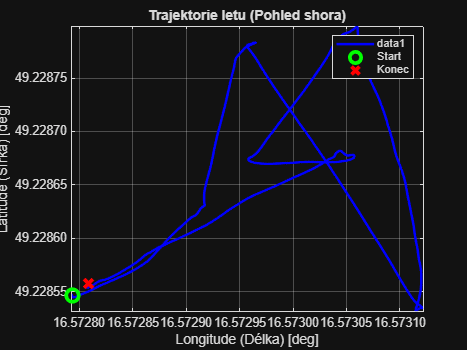


%3. 2D TRASA (MAPA ) jen zkouška zda t ofunguje lololol
figure('Name', 'GPS: 2D Trasa letu (Top View)');
plot(data.GPS.Pos(:,2), data.GPS.Pos(:,1), 'b-', 'LineWidth', 2);
hold on;
% Vykreslíme začátek (Zeleně) a konec (Červeně)
plot(data.GPS.Pos(1,2), data.GPS.Pos(1,1), 'go', 'MarkerSize', 10, 'LineWidth', 3, 'DisplayName', 'Start');
plot(data.GPS.Pos(end,2), data.GPS.Pos(end,1), 'rx', 'MarkerSize', 10, 'LineWidth', 3, 'DisplayName', 'Konec');

title('Trajektorie letu (Pohled shora)');
xlabel('Longitude (Délka) [deg]');
ylabel('Latitude (Šířka) [deg]');
legend; grid on; axis equal;
ax = gca; ax.YAxis.Exponent = 0; ax.XAxis.Exponent = 0;
xtickformat('%.5f'); ytickformat('%.5f');

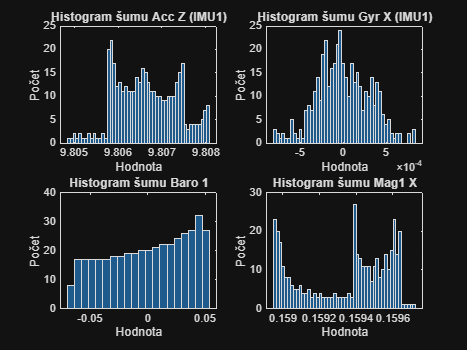





%%VARIANCE
% AKCELEROMETRY
data.IMU1.Var_Acc = var(data.IMU1.Acc(idx_bias, :)); 
data.IMU2.Var_Acc = var(data.IMU2.Acc(idx_bias, :));
data.IMU3.Var_Acc = var(data.IMU3.Acc(idx_bias, :));

% GYROSKOPY
data.IMU1.Var_Gyr = var(data.IMU1.Gyr(idx_bias, :));
data.IMU2.Var_Gyr = var(data.IMU2.Gyr(idx_bias, :));
data.IMU3.Var_Gyr = var(data.IMU3.Gyr(idx_bias, :));

% BAROMETRY
data.Baro1.Var_Alt = var(data.Baro1.Alt(idx_bias));
data.Baro2.Var_Alt = var(data.Baro2.Alt(idx_bias));

% MAGNETOMETRY
data.Mag1.Var_Field = var(data.Mag1.Field(idx_bias, :));
data.Mag2.Var_Field = var(data.Mag2.Field(idx_bias, :));

% GPS
data.GPS.Var_Pos = var(data.GPS.Pos(idx_bias, :));
data.GPS.Var_Spd = var(data.GPS.Spd(idx_bias));
data.GPS.Var_GCRs = var(data.GPS.GCRs(idx_bias));
data.GPS.Var_VZ = var(data.GPS.VZ(idx_bias));


%% VIZUALIZACE ROZLOŽENÍ ŠUMU (HISTOGRAM)
% Ukáže, jestli má šum "Gaussovské" rozložení (což Kalman potřebuje)
%zde si to muzete zobrazit kazdy sam 
figure('Name', 'Analýza šumu (Histogramy)');
subplot(2,2,1);
histogram(data.IMU1.Acc(idx_bias, 3), 50);
title('Histogram šumu Acc Z (IMU1)'); xlabel('Hodnota'); ylabel('Počet');

subplot(2,2,2);
histogram(data.IMU1.Gyr(idx_bias, 1), 50);
title('Histogram šumu Gyr X (IMU1)'); xlabel('Hodnota'); ylabel('Počet');

subplot(2,2,3);
histogram(data.Baro1.Alt(idx_bias), 20);
title('Histogram šumu Baro 1'); xlabel('Hodnota'); ylabel('Počet');

subplot(2,2,4);
histogram(data.Mag1.Field(idx_bias, 1), 50);
title('Histogram šumu Mag1 X'); xlabel('Hodnota'); ylabel('Počet');